tab_CNNLSTM = audioClipObj.roiTable;
labels_CNNLSTM = [tab_CNNLSTM.TimeStart,tab_CNNLSTM.TimeEnd];

tab_DS = audioClipObjDS.roiTable;
labels_ds = [tab_DS.TimeStart,tab_DS.TimeEnd];

times = audioClipObj.times;

labels_spect = {...
    [labels_CNNLSTM,(1:size(labels_CNNLSTM,1))'],'CNN-LSTM';...
    [labels_ds,(1:size(labels_ds,1))'],'DS'};

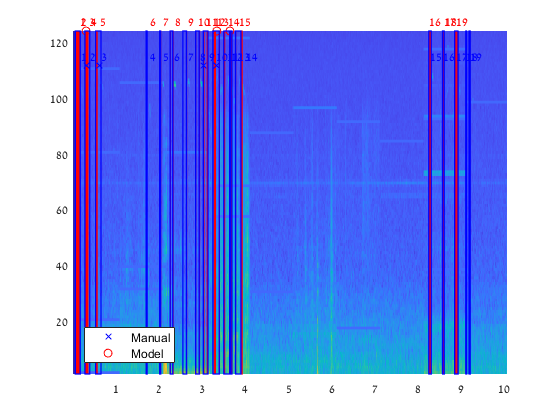

% data = audioClipObj.vec;
data = data_in';
labels = labels_spect;
winlen = [];
max_syllable_size = [];
% fs = audioClipObj.fs;
fs = 330;
mode_flag= 2;
clf;
spectrogram_browser(data,labels,[],winlen,max_syllable_size,fs,mode_flag);